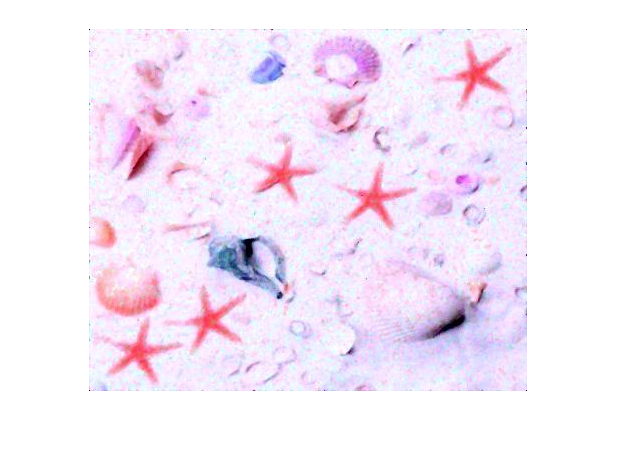

% Computer Vision Coursework Pipeline
% Write the file name to load below, with the extesion, It will
% be expected that it is located within the current directory
FileName = "StarFish_map1.jpg";
%FileName = "starfish_5.jpg";
%Image Variable that will not be editied (Original)
OriginalImage = LoadImage(FileName);

The first task, after loading the image is to analyse the image histogram and decide what to do with the image

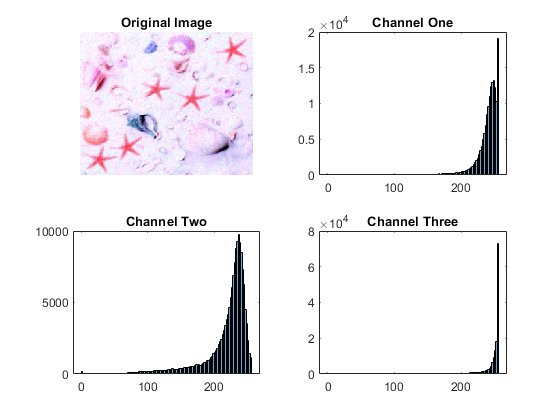

[r,g,b] = ThreeChannelHistorgram(OriginalImage);

red Channel salt and pepper noise


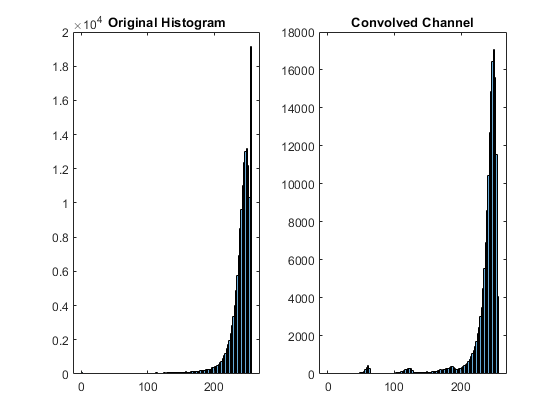

red = OriginalImage(:,:,1);
green = OriginalImage(:,:,2);
blue = OriginalImage(:,:,3);
if r(length(r)) > mean(r) || r(1) > mean(r)
    disp("red Channel salt and pepper noise");
    % Add forloop until above condition is fixed?
    red = SingleChannelConvolve(OriginalImage(:,:,1), 1/(4 * 4) * ones(4));
else 
    red = SingleChannelConvolve(OriginalImage(:,:,1), ones(4));
end

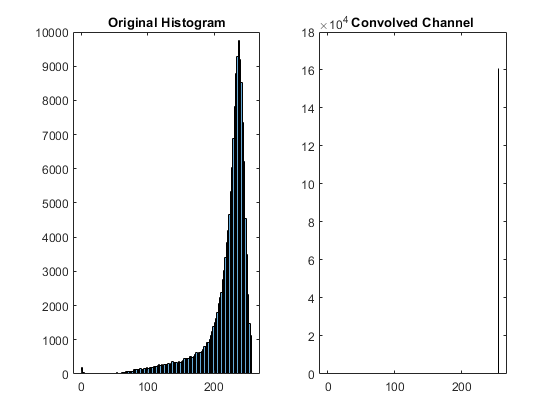

if g(length(g)) > mean(g) || g(1) > mean(g)
    disp("Green Channel Salt and Pepper Noise");
    green = SingleChannelConvolve(OriginalImage(:,:,2), 1/(4 * 4) * ones(4));
else 
    green = SingleChannelConvolve(OriginalImage(:,:,2), ones(4));
end

Blue Channel Salt and Pepper Noise


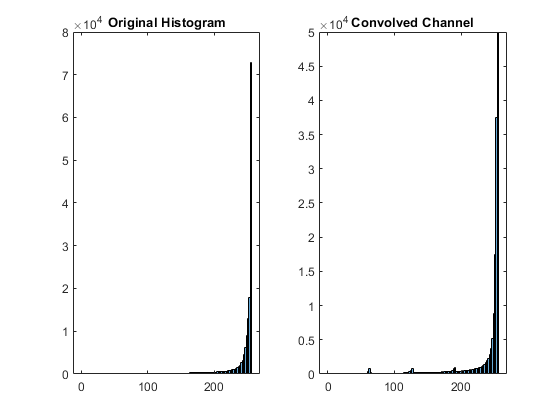

if b(length(b)) > mean(b) || b(1) > mean(b)
    disp("Blue Channel Salt and Pepper Noise")
    blue = SingleChannelConvolve(OriginalImage(:,:,3), 1/(4 * 4) * ones(4));
else 
    blue = SingleChannelConvolve(OriginalImage(:,:,3), ones(4));
end

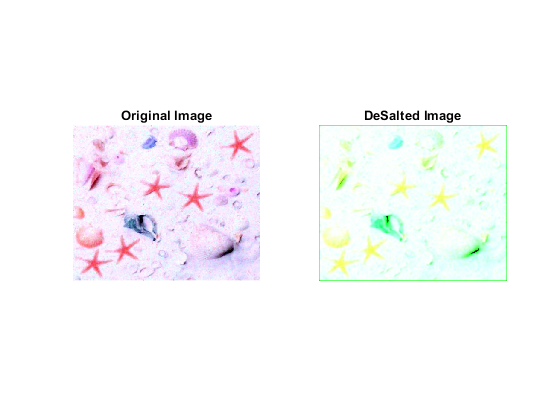

DeSaltedImage = cat(3,red, green, blue);
figure
subplot(1,2,1);
imshow(OriginalImage);
title("Original Image");
subplot(1,2,2);
imshow(DeSaltedImage);
title("DeSalted Image");

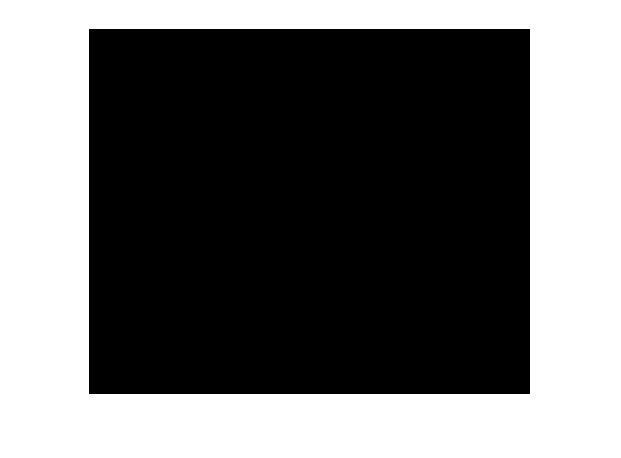

GrayFilteredImage = createMask(DeSaltedImage);
figure
imshow(GrayFilteredImage);

%imshow(imbinarize(GreyFilteredImage,graythresh(GreyFilteredImage)));

## Different Approach using MSER regions

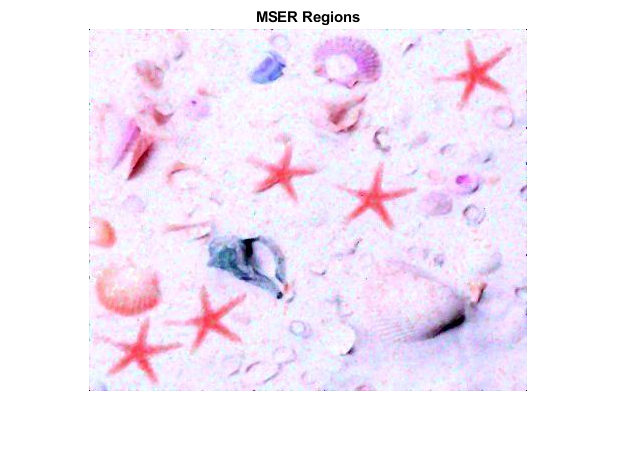

[mserRegions, mserConnComp] = detectMSERFeatures(GrayFilteredImage, 'RegionAreaRange',[700,8000]);
figure
imshow(OriginalImage);
title("MSER Regions");
hold on;
plot(mserRegions, 'showPixelList', true, 'showEllipses', false);
hold off;

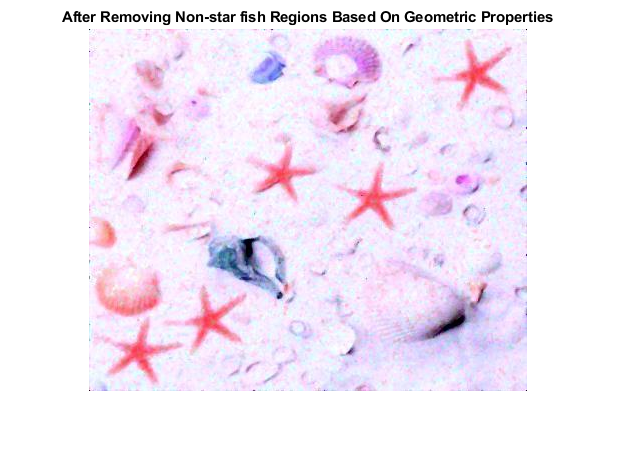

mserStats = regionprops(mserConnComp, 'BoundingBox', 'Eccentricity', ...
     'Solidity', 'Image');
LogMSER(mserStats);

 filterIdx = [mserStats.Eccentricity] > .7;
mserStats(filterIdx) = [];
mserRegions(filterIdx) = [];

figure
 imshow(OriginalImage)
 hold on
 plot(mserRegions, 'showPixelList', true,'showEllipses',false)
 title('After Removing Non-star fish Regions Based On Geometric Properties')
 hold off

## Now moving from image prepocessing to image analysis

%This is a basic outline and may change later
SE = strel('diamond',3);
circle = strel('disk', 3, 4);
smallOct = strel('octagon', 3)

smallOct = strel is a octagon shaped structuring element with properties:

      Neighborhood: [7×7 logical]
    Dimensionality: 2


starAttempt = [1,0,0,0,0,1,0,0,0,0,1,
               0,1,0,0,0,1,0,0,0,1,0,
               0,0,1,0,0,1,0,0,1,0,0,
               0,0,0,1,0,1,0,1,0,0,0,
               0,0,0,0,1,1,1,0,0,0,0,
               1,1,1,1,1,1,1,1,1,1,1,
               0,0,0,0,1,1,1,0,0,0,0,
               0,0,0,1,0,1,0,1,0,0,0,
               0,0,1,0,0,1,0,0,1,0,0,
               0,1,0,0,0,1,0,0,0,1,0,
               1,0,0,0,0,1,0,0,0,0,1];
verySmallStar = [0,1,0,
                        1,1,1,
                        0,1,0];
figure
stepZero = bwareaopen(GrayFilteredImage, 700);
imshow(stepZero);

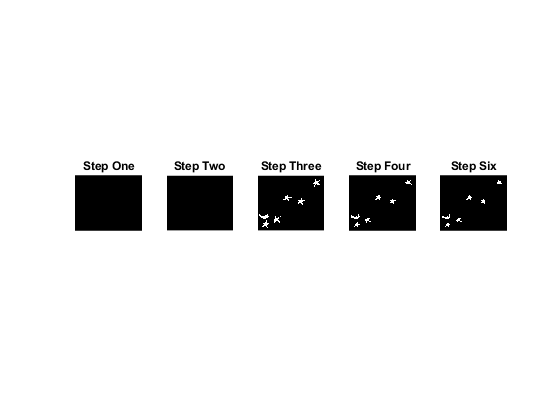

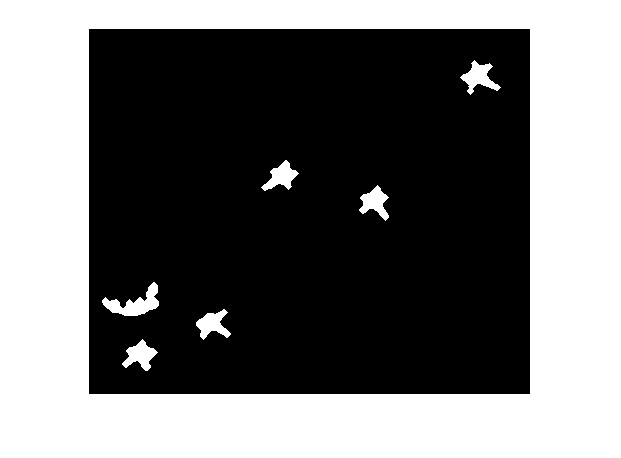

figure
%stepOne = imerode(imclose(GrayFilteredImage, SE),circle);
%imshow(imerode(imopen(imdilate(stepOne, SE),circle),smallOct));
%


stepOne = imopen(imclose(imerode(stepZero, verySmallStar),verySmallStar),circle);
subplot(1,5,1);
imshow(stepOne);
title("Step One")
stepTwo = imdilate(imdilate(imerode(stepOne, circle), verySmallStar), circle);
subplot(1,5,2);
imshow(stepTwo);
title("Step Two")
subplot(1,5,3);
imshow(stepFour);
title("Step Three");
stepFour = imclose(imerode(stepThree, verySmallStar),verySmallStar);
subplot(1,5,4);
stepFive = imopen(imerode(stepFour, verySmallStar), circle);
imshow(stepFive);
title("Step Four");
stepSix = stepFive;
for x = 1:3
    stepSix = imerode(stepSix, verySmallStar);
end
for x = 1:3
    stepSix = imdilate(stepSix, verySmallStar);
end
subplot(1,5,5);
imshow(stepSix);
title("Step Six");

figure
imshow(stepSix);